%calculating the mean first passage time analytically/numerically 
%to investigate effect of invader toehold length on DNA/RNA TMSD kinetics

b = 20 %define branch migration domain length

b = 20

%g = 2 %define invader toehold length

R = 1.987/1000 % universal rate constant in kcal/K/mol 

R = 0.0020

temp = 298.15%temperature in K

temp = 298.1500

%free energy parameters
dGassoc = 2.6*R*temp

dGassoc = 1.5403

dGbp = -2.52*R*temp

dGbp = -1.4929

dGp = 3.6*R*temp

dGp = 2.1327

dGrd = -0.8*R*temp

dGrd = -0.4739

dGbm = 7.4*R*temp 

dGbm = 4.3839

%absolute rate constant 
k_bp = 5.4*10^7

k_bp = 54000000

k_eff = zeros(1,15)

k_eff =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time = zeros(1, 15)

first_pass_time =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


prob_unbound = zeros(1, 15)

prob_unbound =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



%loop through invader toehold lengths
for g = 1:15

    %define forward and reverse transition rates
    k_AA = 0;
    k_AB1 = k_bp * exp(-dGassoc/(R*temp)) * (5*10^-8)
    k_B1A = k_bp * exp(dGbp/(R*temp))
    k_BC1ij = k_bp;
    k_BC1ji = k_bp * exp(dGbp/(R*temp));
    k_C1f = k_bp * exp(-(dGbm + dGp - dGrd)/(R*temp))
    k_Cf = k_bp * exp(-(dGbm - dGrd)/(R*temp))
    k_Cr = k_bp * exp(-dGbm/(R*temp));
    k_CD = k_bp * exp(-(dGbm - dGrd)/(R*temp));
    k_DC = 0 
    k_DD = 1
    
    %create arrays of forward and reverse transition rates
    if g == 1
        Kf = [k_DD, k_CD, repmat(k_Cf, [1, b-2]), k_C1f, k_AB1]
        Kb = [k_DC, repmat(k_Cr, [1, b-2]), k_Cr, k_B1A, k_AA]
        
    else
        Kf = [k_DD, k_CD, repmat(k_Cf, [1, b-2]), k_C1f, repmat(k_BC1ij, [1, g-2]), k_BC1ij, k_AB1]
        Kb = [k_DC, repmat(k_Cr, [1, b-2]), k_Cr, k_BC1ji, repmat(k_BC1ji, [1, g-2]), k_B1A, k_AA]
    end
    
    Pn_j0 = zeros(1,numel(Kf))
    Pn_j0 (1) = 0
    %calculate flux between each state
    for Pn = 2:numel(Kf)
        Pn_j0(Pn)  = 1/Kf(Pn) + Kb(Pn-1)/Kf(Pn)*Pn_j0(Pn-1)
    end

    first_pass_time (g) = sum(Pn_j0)%calculate first passage time
    k_eff (g) = 1/(first_pass_time (g)*(5*10^-8)) %calculate effective rate constant
    prob_unbound(g) = Pn_j0(end)/sum(Pn_j0) %calculate probability of being in unbound state
end

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 405.2461

k_Cf = 1.4831e+04

k_DC = 0

k_DD = 1

Kf = 	1.0e+04 *

    0.0001    1.4831    1.4831    1.4831    1.4831    1.4831    1.4831    1.4831    1.4831    1.4831    1.4831    1.4831    1.4831    1.4831    1.4831    1.4831    1.4831    1.4831    1.4831    1.4831    0.0405    0.0000


Kb = 	1.0e+06 *

         0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448         0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 = 	1.0e+-4 *

         0    0.6743         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 = 	1.0e+-3 *

         0    0.0674    0.2175         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 = 	1.0e+-3 *

         0    0.0674    0.2175    0.5514         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649    0.8123         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649    0.8123    1.8078         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649    0.8123    1.8078    4.0233         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649    0.8123    1.8078    4.0233    8.9541         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649    0.8123    1.8078    4.0233    8.9541   19.9279         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649    0.8123    1.8078    4.0233    8.9541   19.9279   44.3504         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649    0.8123    1.8078    4.0233    8.9541   19.9279   44.3504   98.7037         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649    0.8123    1.8078    4.0233    8.9541   19.9279   44.3504   98.7037  219.6692         0         0


Pn_j0 = 	1.0e+04 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0009    0.0020    0.0044    0.0099    0.0220    1.7892         0


Pn_j0 = 	1.0e+11 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    3.8765


first_pass_time = 	1.0e+11 *

    3.8765         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff = 	1.0e+-4 *

    0.5159         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 405.2461

k_Cf = 1.4831e+04

k_DC = 0

k_DD = 1

Kf = 	1.0e+07 *

    0.0000    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0000    5.4000    0.0000


Kb = 	1.0e+06 *

         0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448         0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 = 	1.0e+-4 *

         0    0.6743         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 = 	1.0e+-3 *

         0    0.0674    0.2175         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 = 	1.0e+-3 *

         0    0.0674    0.2175    0.5514         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649    0.8123         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649    0.8123    1.8078         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649    0.8123    1.8078    4.0233         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649    0.8123    1.8078    4.0233    8.9541         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649    0.8123    1.8078    4.0233    8.9541   19.9279         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649    0.8123    1.8078    4.0233    8.9541   19.9279   44.3504         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649    0.8123    1.8078    4.0233    8.9541   19.9279   44.3504   98.7037         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649    0.8123    1.8078    4.0233    8.9541   19.9279   44.3504   98.7037  219.6692         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0009    0.0020    0.0044    0.0099    0.0220    1.7892         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0009    0.0020    0.0044    0.0099    0.0220    1.7892    0.1440         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    3.1190


first_pass_time =     3.8765    0.3119         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =     0.0516    0.6412         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 405.2461

k_Cf = 1.4831e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0000    5.4000    5.4000    0.0000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448         0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =          0    0.6743         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0674    0.2175         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0674    0.2175    0.5514         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649    0.8123         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649    0.8123    1.8078         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649    0.8123    1.8078    4.0233         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649    0.8123    1.8078    4.0233    8.9541         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649    0.8123    1.8078    4.0233    8.9541   19.9279         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649    0.8123    1.8078    4.0233    8.9541   19.9279   44.3504         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649    0.8123    1.8078    4.0233    8.9541   19.9279   44.3504   98.7037         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649    0.8123    1.8078    4.0233    8.9541   19.9279   44.3504   98.7037  219.6692         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0009    0.0020    0.0044    0.0099    0.0220    1.7892         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0009    0.0020    0.0044    0.0099    0.0220    1.7892    0.1440         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0009    0.0020    0.0044    0.0099    0.0220    1.7892    0.1440    0.0116         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    2.5095


first_pass_time =     3.8765    0.3119    0.0251         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =     0.0001    0.0006    0.0080         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 405.2461

k_Cf = 1.4831e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0000    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448         0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =          0    0.6743         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0674    0.2175         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0674    0.2175    0.5514         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649    0.8123         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649    0.8123    1.8078         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649    0.8123    1.8078    4.0233         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649    0.8123    1.8078    4.0233    8.9541         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649    0.8123    1.8078    4.0233    8.9541   19.9279         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649    0.8123    1.8078    4.0233    8.9541   19.9279   44.3504         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649    0.8123    1.8078    4.0233    8.9541   19.9279   44.3504   98.7037         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649    0.8123    1.8078    4.0233    8.9541   19.9279   44.3504   98.7037  219.6692         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0009    0.0020    0.0044    0.0099    0.0220    1.7892         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0009    0.0020    0.0044    0.0099    0.0220    1.7892    0.1440         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0009    0.0020    0.0044    0.0099    0.0220    1.7892    0.1440    0.0116         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0009    0.0020    0.0044    0.0099    0.0220    1.7892    0.1440    0.0116    0.0009         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0000    0.0000    0.0000    2.0192


first_pass_time =     3.8765    0.3119    0.0251    0.0020         0         0         0         0         0         0         0         0         0         0         0


k_eff =     0.0001    0.0006    0.0080    0.0990         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 405.2461

k_Cf = 1.4831e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448    4.3448         0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =          0    0.6743         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0674    0.2175         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0674    0.2175    0.5514         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649    0.8123         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649    0.8123    1.8078         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649    0.8123    1.8078    4.0233         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649    0.8123    1.8078    4.0233    8.9541         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649    0.8123    1.8078    4.0233    8.9541   19.9279         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649    0.8123    1.8078    4.0233    8.9541   19.9279   44.3504         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649    0.8123    1.8078    4.0233    8.9541   19.9279   44.3504   98.7037         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649    0.8123    1.8078    4.0233    8.9541   19.9279   44.3504   98.7037  219.6692         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0009    0.0020    0.0044    0.0099    0.0220    1.7892         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0009    0.0020    0.0044    0.0099    0.0220    1.7892    0.1440         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0009    0.0020    0.0044    0.0099    0.0220    1.7892    0.1440    0.0116         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0009    0.0020    0.0044    0.0099    0.0220    1.7892    0.1440    0.0116    0.0009         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0009    0.0020    0.0044    0.0099    0.0220    1.7892    0.1440    0.0116    0.0009    0.0001         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0018    0.0001    0.0000    0.0000    0.0000    1.6246


first_pass_time =     3.8765    0.3119    0.0251    0.0020    0.0002         0         0         0         0         0         0         0         0         0         0


k_eff =     0.0001    0.0006    0.0080    0.0990    1.2296         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9988         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 405.2461

k_Cf = 1.4831e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448         0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =          0    0.6743         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0674    0.2175         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0674    0.2175    0.5514         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649    0.8123         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649    0.8123    1.8078         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649    0.8123    1.8078    4.0233         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649    0.8123    1.8078    4.0233    8.9541         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649    0.8123    1.8078    4.0233    8.9541   19.9279         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649    0.8123    1.8078    4.0233    8.9541   19.9279   44.3504         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649    0.8123    1.8078    4.0233    8.9541   19.9279   44.3504   98.7037         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649    0.8123    1.8078    4.0233    8.9541   19.9279   44.3504   98.7037  219.6692         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0009    0.0020    0.0044    0.0099    0.0220    1.7892         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0009    0.0020    0.0044    0.0099    0.0220    1.7892    0.1440         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0009    0.0020    0.0044    0.0099    0.0220    1.7892    0.1440    0.0116         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0009    0.0020    0.0044    0.0099    0.0220    1.7892    0.1440    0.0116    0.0009         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0009    0.0020    0.0044    0.0099    0.0220    1.7892    0.1440    0.0116    0.0009    0.0001         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0009    0.0020    0.0044    0.0099    0.0220    1.7892    0.1440    0.0116    0.0009    0.0001    0.0000         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0179    0.0014    0.0001    0.0000    0.0000    0.0000    1.3072


first_pass_time =     3.8765    0.3119    0.0251    0.0020    0.0002    0.0000         0         0         0         0         0         0         0         0         0


k_eff =     0.0001    0.0006    0.0080    0.0990    1.2296   15.0714         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9988    0.9850         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 405.2461

k_Cf = 1.4831e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448         0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =          0    0.6743         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0674    0.2175         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0674    0.2175    0.5514         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649    0.8123         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649    0.8123    1.8078         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649    0.8123    1.8078    4.0233         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649    0.8123    1.8078    4.0233    8.9541         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649    0.8123    1.8078    4.0233    8.9541   19.9279         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649    0.8123    1.8078    4.0233    8.9541   19.9279   44.3504         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649    0.8123    1.8078    4.0233    8.9541   19.9279   44.3504   98.7037         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649    0.8123    1.8078    4.0233    8.9541   19.9279   44.3504   98.7037  219.6692         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0009    0.0020    0.0044    0.0099    0.0220    1.7892         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0009    0.0020    0.0044    0.0099    0.0220    1.7892    0.1440         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0009    0.0020    0.0044    0.0099    0.0220    1.7892    0.1440    0.0116         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0009    0.0020    0.0044    0.0099    0.0220    1.7892    0.1440    0.0116    0.0009         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0009    0.0020    0.0044    0.0099    0.0220    1.7892    0.1440    0.0116    0.0009    0.0001         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0009    0.0020    0.0044    0.0099    0.0220    1.7892    0.1440    0.0116    0.0009    0.0001    0.0000         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0009    0.0020    0.0044    0.0099    0.0220    1.7892    0.1440    0.0116    0.0009    0.0001    0.0000    0.0000         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0010    0.0022    0.1789    0.0144    0.0012    0.0001    0.0000    0.0000    0.0000    1.0518


first_pass_time =     3.8765    0.3119    0.0251    0.0020    0.0002    0.0000    0.0000         0         0         0         0         0         0         0         0


k_eff =     0.0001    0.0006    0.0080    0.0990    1.2296   15.0714  159.9545         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9988    0.9850    0.8412         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 405.2461

k_Cf = 1.4831e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448         0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =          0    0.6743         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0674    0.2175         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0674    0.2175    0.5514         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649    0.8123         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649    0.8123    1.8078         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649    0.8123    1.8078    4.0233         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649    0.8123    1.8078    4.0233    8.9541         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649    0.8123    1.8078    4.0233    8.9541   19.9279         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649    0.8123    1.8078    4.0233    8.9541   19.9279   44.3504         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649    0.8123    1.8078    4.0233    8.9541   19.9279   44.3504   98.7037         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649    0.8123    1.8078    4.0233    8.9541   19.9279   44.3504   98.7037  219.6692         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0009    0.0020    0.0044    0.0099    0.0220    1.7892         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0009    0.0020    0.0044    0.0099    0.0220    1.7892    0.1440         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0009    0.0020    0.0044    0.0099    0.0220    1.7892    0.1440    0.0116         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0009    0.0020    0.0044    0.0099    0.0220    1.7892    0.1440    0.0116    0.0009         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0009    0.0020    0.0044    0.0099    0.0220    1.7892    0.1440    0.0116    0.0009    0.0001         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0009    0.0020    0.0044    0.0099    0.0220    1.7892    0.1440    0.0116    0.0009    0.0001    0.0000         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0009    0.0020    0.0044    0.0099    0.0220    1.7892    0.1440    0.0116    0.0009    0.0001    0.0000    0.0000         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0009    0.0020    0.0044    0.0099    0.0220    1.7892    0.1440    0.0116    0.0009    0.0001    0.0000    0.0000    0.0000         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0009    0.0020    0.0044    0.0099    0.0220    1.7892    0.1440    0.0116    0.0009    0.0001    0.0000    0.0000    0.0000    0.8468


first_pass_time =     3.8765    0.3119    0.0251    0.0020    0.0002    0.0000    0.0000    0.0000         0         0         0         0         0         0         0


k_eff =     0.0001    0.0006    0.0080    0.0990    1.2296   15.0714  159.9545  706.1059         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9988    0.9850    0.8412    0.2990         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 405.2461

k_Cf = 1.4831e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448         0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =          0    0.6743         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0674    0.2175         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0674    0.2175    0.5514         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649    0.8123         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649    0.8123    1.8078         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649    0.8123    1.8078    4.0233         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649    0.8123    1.8078    4.0233    8.9541         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649    0.8123    1.8078    4.0233    8.9541   19.9279         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649    0.8123    1.8078    4.0233    8.9541   19.9279   44.3504         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649    0.8123    1.8078    4.0233    8.9541   19.9279   44.3504   98.7037         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649    0.8123    1.8078    4.0233    8.9541   19.9279   44.3504   98.7037  219.6692         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0009    0.0020    0.0044    0.0099    0.0220    1.7892         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0009    0.0020    0.0044    0.0099    0.0220    1.7892    0.1440         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0009    0.0020    0.0044    0.0099    0.0220    1.7892    0.1440    0.0116         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0009    0.0020    0.0044    0.0099    0.0220    1.7892    0.1440    0.0116    0.0009         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0009    0.0020    0.0044    0.0099    0.0220    1.7892    0.1440    0.0116    0.0009    0.0001         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0009    0.0020    0.0044    0.0099    0.0220    1.7892    0.1440    0.0116    0.0009    0.0001    0.0000         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0009    0.0020    0.0044    0.0099    0.0220    1.7892    0.1440    0.0116    0.0009    0.0001    0.0000    0.0000         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0009    0.0020    0.0044    0.0099    0.0220    1.7892    0.1440    0.0116    0.0009    0.0001    0.0000    0.0000    0.0000         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0009    0.0020    0.0044    0.0099    0.0220    1.7892    0.1440    0.0116    0.0009    0.0001    0.0000    0.0000    0.0000    0.0000         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0009    0.0020    0.0044    0.0099    0.0220    1.7892    0.1440    0.0116    0.0009    0.0001    0.0000    0.0000    0.0000    0.0000    0.0686


first_pass_time =     3.8765    0.3119    0.0251    0.0020    0.0002    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0


k_eff =     0.0001    0.0006    0.0080    0.0990    1.2296   15.0714  159.9545  706.1059  973.5667         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9988    0.9850    0.8412    0.2990    0.0334         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 405.2461

k_Cf = 1.4831e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =          0    0.6743         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0674    0.2175         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0674    0.2175    0.5514         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649    0.8123         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649    0.8123    1.8078         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649    0.8123    1.8078    4.0233         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649    0.8123    1.8078    4.0233    8.9541         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649    0.8123    1.8078    4.0233    8.9541   19.9279         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649    0.8123    1.8078    4.0233    8.9541   19.9279   44.3504         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649    0.8123    1.8078    4.0233    8.9541   19.9279   44.3504   98.7037         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649    0.8123    1.8078    4.0233    8.9541   19.9279   44.3504   98.7037  219.6692         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0009    0.0020    0.0044    0.0099    0.0220    1.7892         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0009    0.0020    0.0044    0.0099    0.0220    1.7892    0.1440         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0009    0.0020    0.0044    0.0099    0.0220    1.7892    0.1440    0.0116         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0009    0.0020    0.0044    0.0099    0.0220    1.7892    0.1440    0.0116    0.0009         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0009    0.0020    0.0044    0.0099    0.0220    1.7892    0.1440    0.0116    0.0009    0.0001         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0009    0.0020    0.0044    0.0099    0.0220    1.7892    0.1440    0.0116    0.0009    0.0001    0.0000         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0009    0.0020    0.0044    0.0099    0.0220    1.7892    0.1440    0.0116    0.0009    0.0001    0.0000    0.0000         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0009    0.0020    0.0044    0.0099    0.0220    1.7892    0.1440    0.0116    0.0009    0.0001    0.0000    0.0000    0.0000         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0009    0.0020    0.0044    0.0099    0.0220    1.7892    0.1440    0.0116    0.0009    0.0001    0.0000    0.0000    0.0000    0.0000         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0009    0.0020    0.0044    0.0099    0.0220    1.7892    0.1440    0.0116    0.0009    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0009    0.0020    0.0044    0.0099    0.0220    1.7892    0.1440    0.0116    0.0009    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000


first_pass_time =     3.8765    0.3119    0.0251    0.0020    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


k_eff =     0.0000    0.0000    0.0000    0.0001    0.0012    0.0151    0.1600    0.7061    0.9736    1.0042         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9988    0.9850    0.8412    0.2990    0.0334    0.0030         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 405.2461

k_Cf = 1.4831e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =          0    0.6743         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0674    0.2175         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0674    0.2175    0.5514         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649    0.8123         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649    0.8123    1.8078         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649    0.8123    1.8078    4.0233         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649    0.8123    1.8078    4.0233    8.9541         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649    0.8123    1.8078    4.0233    8.9541   19.9279         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649    0.8123    1.8078    4.0233    8.9541   19.9279   44.3504         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649    0.8123    1.8078    4.0233    8.9541   19.9279   44.3504   98.7037         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649    0.8123    1.8078    4.0233    8.9541   19.9279   44.3504   98.7037  219.6692         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0009    0.0020    0.0044    0.0099    0.0220    1.7892         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0009    0.0020    0.0044    0.0099    0.0220    1.7892    0.1440         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0009    0.0020    0.0044    0.0099    0.0220    1.7892    0.1440    0.0116         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0009    0.0020    0.0044    0.0099    0.0220    1.7892    0.1440    0.0116    0.0009         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0009    0.0020    0.0044    0.0099    0.0220    1.7892    0.1440    0.0116    0.0009    0.0001         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0009    0.0020    0.0044    0.0099    0.0220    1.7892    0.1440    0.0116    0.0009    0.0001    0.0000         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0009    0.0020    0.0044    0.0099    0.0220    1.7892    0.1440    0.0116    0.0009    0.0001    0.0000    0.0000         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0009    0.0020    0.0044    0.0099    0.0220    1.7892    0.1440    0.0116    0.0009    0.0001    0.0000    0.0000    0.0000         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0009    0.0020    0.0044    0.0099    0.0220    1.7892    0.1440    0.0116    0.0009    0.0001    0.0000    0.0000    0.0000    0.0000         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0009    0.0020    0.0044    0.0099    0.0220    1.7892    0.1440    0.0116    0.0009    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0009    0.0020    0.0044    0.0099    0.0220    1.7892    0.1440    0.0116    0.0009    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0009    0.0020    0.0044    0.0099    0.0220    1.7892    0.1440    0.0116    0.0009    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000


first_pass_time =     3.8765    0.3119    0.0251    0.0020    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0


k_eff =     0.0000    0.0000    0.0000    0.0001    0.0012    0.0151    0.1600    0.7061    0.9736    1.0042    1.0067         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9988    0.9850    0.8412    0.2990    0.0334    0.0030    0.0005         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 405.2461

k_Cf = 1.4831e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =          0    0.6743         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0674    0.2175         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0674    0.2175    0.5514         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649    0.8123         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649    0.8123    1.8078         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649    0.8123    1.8078    4.0233         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649    0.8123    1.8078    4.0233    8.9541         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649    0.8123    1.8078    4.0233    8.9541   19.9279         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649    0.8123    1.8078    4.0233    8.9541   19.9279   44.3504         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649    0.8123    1.8078    4.0233    8.9541   19.9279   44.3504   98.7037         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649    0.8123    1.8078    4.0233    8.9541   19.9279   44.3504   98.7037  219.6692         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0009    0.0020    0.0044    0.0099    0.0220    1.7892         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0009    0.0020    0.0044    0.0099    0.0220    1.7892    0.1440         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0009    0.0020    0.0044    0.0099    0.0220    1.7892    0.1440    0.0116         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0009    0.0020    0.0044    0.0099    0.0220    1.7892    0.1440    0.0116    0.0009         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0009    0.0020    0.0044    0.0099    0.0220    1.7892    0.1440    0.0116    0.0009    0.0001         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0009    0.0020    0.0044    0.0099    0.0220    1.7892    0.1440    0.0116    0.0009    0.0001    0.0000         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0009    0.0020    0.0044    0.0099    0.0220    1.7892    0.1440    0.0116    0.0009    0.0001    0.0000    0.0000         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0009    0.0020    0.0044    0.0099    0.0220    1.7892    0.1440    0.0116    0.0009    0.0001    0.0000    0.0000    0.0000         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0009    0.0020    0.0044    0.0099    0.0220    1.7892    0.1440    0.0116    0.0009    0.0001    0.0000    0.0000    0.0000    0.0000         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0009    0.0020    0.0044    0.0099    0.0220    1.7892    0.1440    0.0116    0.0009    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0009    0.0020    0.0044    0.0099    0.0220    1.7892    0.1440    0.0116    0.0009    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0009    0.0020    0.0044    0.0099    0.0220    1.7892    0.1440    0.0116    0.0009    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0009    0.0020    0.0044    0.0099    0.0220    1.7892    0.1440    0.0116    0.0009    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000


first_pass_time =     3.8765    0.3119    0.0251    0.0020    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0


k_eff =     0.0000    0.0000    0.0000    0.0001    0.0012    0.0151    0.1600    0.7061    0.9736    1.0042    1.0067    1.0069         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9988    0.9850    0.8412    0.2990    0.0334    0.0030    0.0005    0.0003         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 405.2461

k_Cf = 1.4831e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =          0    0.6743         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0674    0.2175         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0674    0.2175    0.5514         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649    0.8123         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649    0.8123    1.8078         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649    0.8123    1.8078    4.0233         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649    0.8123    1.8078    4.0233    8.9541         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649    0.8123    1.8078    4.0233    8.9541   19.9279         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649    0.8123    1.8078    4.0233    8.9541   19.9279   44.3504         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649    0.8123    1.8078    4.0233    8.9541   19.9279   44.3504   98.7037         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649    0.8123    1.8078    4.0233    8.9541   19.9279   44.3504   98.7037  219.6692         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0009    0.0020    0.0044    0.0099    0.0220    1.7892         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0009    0.0020    0.0044    0.0099    0.0220    1.7892    0.1440         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0009    0.0020    0.0044    0.0099    0.0220    1.7892    0.1440    0.0116         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0009    0.0020    0.0044    0.0099    0.0220    1.7892    0.1440    0.0116    0.0009         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0009    0.0020    0.0044    0.0099    0.0220    1.7892    0.1440    0.0116    0.0009    0.0001         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0009    0.0020    0.0044    0.0099    0.0220    1.7892    0.1440    0.0116    0.0009    0.0001    0.0000         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0009    0.0020    0.0044    0.0099    0.0220    1.7892    0.1440    0.0116    0.0009    0.0001    0.0000    0.0000         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0009    0.0020    0.0044    0.0099    0.0220    1.7892    0.1440    0.0116    0.0009    0.0001    0.0000    0.0000    0.0000         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0009    0.0020    0.0044    0.0099    0.0220    1.7892    0.1440    0.0116    0.0009    0.0001    0.0000    0.0000    0.0000    0.0000         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0009    0.0020    0.0044    0.0099    0.0220    1.7892    0.1440    0.0116    0.0009    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0009    0.0020    0.0044    0.0099    0.0220    1.7892    0.1440    0.0116    0.0009    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0009    0.0020    0.0044    0.0099    0.0220    1.7892    0.1440    0.0116    0.0009    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0009    0.0020    0.0044    0.0099    0.0220    1.7892    0.1440    0.0116    0.0009    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0009    0.0020    0.0044    0.0099    0.0220    1.7892    0.1440    0.0116    0.0009    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000


first_pass_time =     3.8765    0.3119    0.0251    0.0020    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0


k_eff =     0.0000    0.0000    0.0000    0.0001    0.0012    0.0151    0.1600    0.7061    0.9736    1.0042    1.0067    1.0069    1.0069         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9988    0.9850    0.8412    0.2990    0.0334    0.0030    0.0005    0.0003    0.0003         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 405.2461

k_Cf = 1.4831e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =          0    0.6743         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0674    0.2175         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0674    0.2175    0.5514         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649    0.8123         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649    0.8123    1.8078         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649    0.8123    1.8078    4.0233         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649    0.8123    1.8078    4.0233    8.9541         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649    0.8123    1.8078    4.0233    8.9541   19.9279         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649    0.8123    1.8078    4.0233    8.9541   19.9279   44.3504         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649    0.8123    1.8078    4.0233    8.9541   19.9279   44.3504   98.7037         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649    0.8123    1.8078    4.0233    8.9541   19.9279   44.3504   98.7037  219.6692         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0009    0.0020    0.0044    0.0099    0.0220    1.7892         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0009    0.0020    0.0044    0.0099    0.0220    1.7892    0.1440         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0009    0.0020    0.0044    0.0099    0.0220    1.7892    0.1440    0.0116         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0009    0.0020    0.0044    0.0099    0.0220    1.7892    0.1440    0.0116    0.0009         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0009    0.0020    0.0044    0.0099    0.0220    1.7892    0.1440    0.0116    0.0009    0.0001         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0009    0.0020    0.0044    0.0099    0.0220    1.7892    0.1440    0.0116    0.0009    0.0001    0.0000         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0009    0.0020    0.0044    0.0099    0.0220    1.7892    0.1440    0.0116    0.0009    0.0001    0.0000    0.0000         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0009    0.0020    0.0044    0.0099    0.0220    1.7892    0.1440    0.0116    0.0009    0.0001    0.0000    0.0000    0.0000         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0009    0.0020    0.0044    0.0099    0.0220    1.7892    0.1440    0.0116    0.0009    0.0001    0.0000    0.0000    0.0000    0.0000         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0009    0.0020    0.0044    0.0099    0.0220    1.7892    0.1440    0.0116    0.0009    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0009    0.0020    0.0044    0.0099    0.0220    1.7892    0.1440    0.0116    0.0009    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0009    0.0020    0.0044    0.0099    0.0220    1.7892    0.1440    0.0116    0.0009    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0009    0.0020    0.0044    0.0099    0.0220    1.7892    0.1440    0.0116    0.0009    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0009    0.0020    0.0044    0.0099    0.0220    1.7892    0.1440    0.0116    0.0009    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0009    0.0020    0.0044    0.0099    0.0220    1.7892    0.1440    0.0116    0.0009    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000


first_pass_time =     3.8765    0.3119    0.0251    0.0020    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0


k_eff =     0.0000    0.0000    0.0000    0.0001    0.0012    0.0151    0.1600    0.7061    0.9736    1.0042    1.0067    1.0069    1.0069    1.0069         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9988    0.9850    0.8412    0.2990    0.0334    0.0030    0.0005    0.0003    0.0003    0.0003         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 405.2461

k_Cf = 1.4831e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0015    0.0000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Pn_j0 =          0    0.6743         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0674    0.2175         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0674    0.2175    0.5514         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649    0.8123         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649    0.8123    1.8078         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649    0.8123    1.8078    4.0233         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649    0.8123    1.8078    4.0233    8.9541         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649    0.8123    1.8078    4.0233    8.9541   19.9279         0         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649    0.8123    1.8078    4.0233    8.9541   19.9279   44.3504         0         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649    0.8123    1.8078    4.0233    8.9541   19.9279   44.3504   98.7037         0         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0001    0.0002    0.0006    0.0013    0.0029    0.0066    0.0148    0.0331    0.0736    0.1639    0.3649    0.8123    1.8078    4.0233    8.9541   19.9279   44.3504   98.7037  219.6692         0         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0009    0.0020    0.0044    0.0099    0.0220    1.7892         0         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0009    0.0020    0.0044    0.0099    0.0220    1.7892    0.1440         0         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0009    0.0020    0.0044    0.0099    0.0220    1.7892    0.1440    0.0116         0         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0009    0.0020    0.0044    0.0099    0.0220    1.7892    0.1440    0.0116    0.0009         0         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0009    0.0020    0.0044    0.0099    0.0220    1.7892    0.1440    0.0116    0.0009    0.0001         0         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0009    0.0020    0.0044    0.0099    0.0220    1.7892    0.1440    0.0116    0.0009    0.0001    0.0000         0         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0009    0.0020    0.0044    0.0099    0.0220    1.7892    0.1440    0.0116    0.0009    0.0001    0.0000    0.0000         0         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0009    0.0020    0.0044    0.0099    0.0220    1.7892    0.1440    0.0116    0.0009    0.0001    0.0000    0.0000    0.0000         0         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0009    0.0020    0.0044    0.0099    0.0220    1.7892    0.1440    0.0116    0.0009    0.0001    0.0000    0.0000    0.0000    0.0000         0


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0009    0.0020    0.0044    0.0099    0.0220    1.7892    0.1440    0.0116    0.0009    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0009    0.0020    0.0044    0.0099    0.0220    1.7892    0.1440    0.0116    0.0009    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0009    0.0020    0.0044    0.0099    0.0220    1.7892    0.1440    0.0116    0.0009    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0009    0.0020    0.0044    0.0099    0.0220    1.7892    0.1440    0.0116    0.0009    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0009    0.0020    0.0044    0.0099    0.0220    1.7892    0.1440    0.0116    0.0009    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0009    0.0020    0.0044    0.0099    0.0220    1.7892    0.1440    0.0116    0.0009    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000


Pn_j0 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0009    0.0020    0.0044    0.0099    0.0220    1.7892    0.1440    0.0116    0.0009    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000


first_pass_time =     3.8765    0.3119    0.0251    0.0020    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


k_eff =     0.0000    0.0000    0.0000    0.0001    0.0012    0.0151    0.1600    0.7061    0.9736    1.0042    1.0067    1.0069    1.0069    1.0069    1.0069


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9988    0.9850    0.8412    0.2990    0.0334    0.0030    0.0005    0.0003    0.0003    0.0003    0.0003


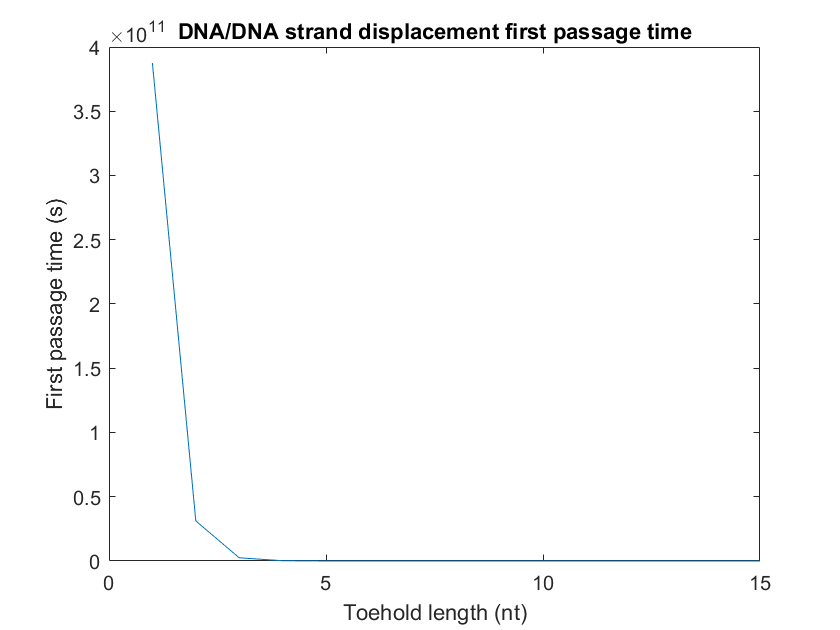

plot(1:15, first_pass_time)
ylabel('First passage time (s)')
xlabel('Toehold length (nt)')
title('DNA/DNA strand displacement first passage time')

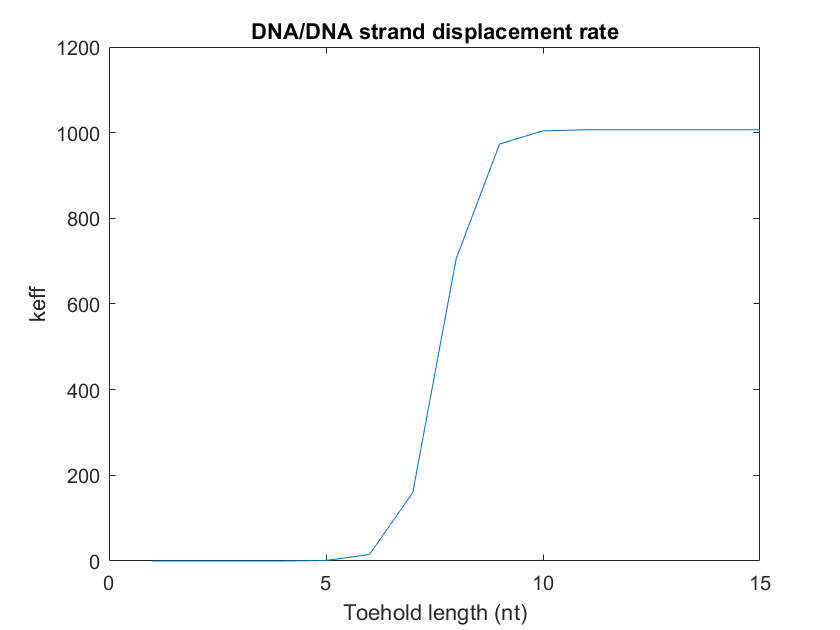


plot(1:15, k_eff)
xlabel('Toehold length (nt)')
ylabel('keff')
title('DNA/DNA strand displacement rate')

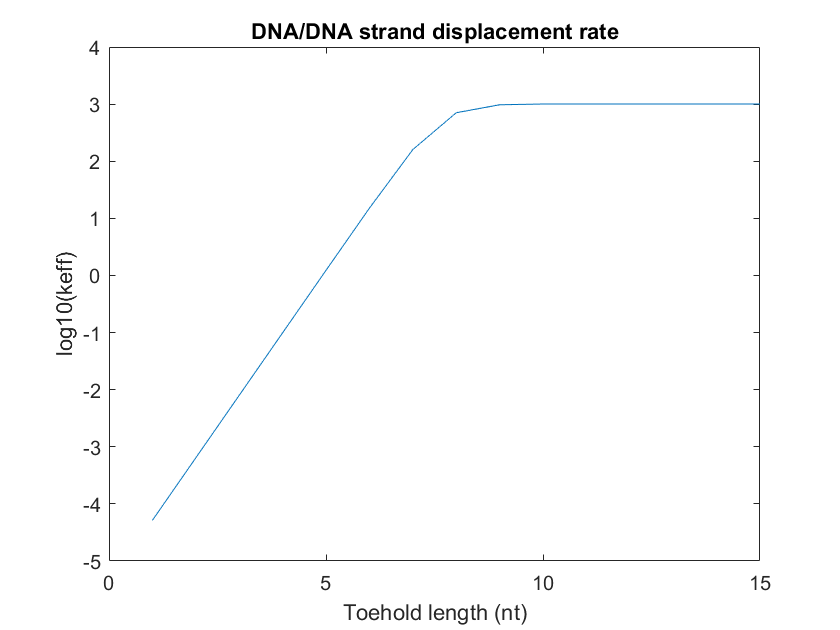


plot(1:15, log10(k_eff))
xlabel('Toehold length (nt)')
ylabel('log10(keff)')
title('DNA/DNA strand displacement rate')  